# Detekcja twarzy

Autor: Szymon Tokarz

Data:8.10.2024 r.

## Rezultaty

model = createSkinModel('model_skory.bmp');
mesh(model)

figure;imagesc(model);colormap(jet)
figure;imagesc(model2);colormap(jet)

addpath('BazaObrazow')

testowy = imread('testowy_0_0000.jpeg');
figure, subplot(2,3,1), imshow(testowy);


szary2 = probabilityIM(testowy,model2);
subplot(2,3,2), imshow(szary2,[])
colormap(gray);


level =0.001514

level = 0.0015

binarny = im2bw(szary2, level);
subplot(2,3,3), imshow(binarny);

se = strel('disk', 6);% dobierz parametry element strukturalnego
zamkniety = imclose(binarny, se);
subplot(2,3,4), imshow(zamkniety);

label1 = bwlabel(zamkniety);
res = regionprops(label1)

res = 8×1 struct array with fields:
    Area
    Centroid
    BoundingBox


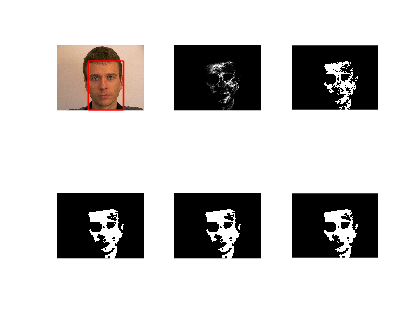

[res.Area];
wyczyszczony = bwareaopen(zamkniety,400); % dobierz parametry
subplot(2,3,5), imshow(wyczyszczony);

[x1, x2, twarz] = szukaj_twarz(wyczyszczony);
subplot(2,3,6), imshow(twarz);
%dodatkowa wizualizacja
subplot(2,3,1)
pos=[x1(2) x1(1) x2(2)-x1(2) x2(1)-x1(1)];
hold on;rectangle('Position',pos,'EdgeColor','red'); hold off

%Drugie zdjęcie testowe
testowy = imread('testowy_0_0004.jpeg');
figure, subplot(2,3,1), imshow(testowy);


szary2 = probabilityIM(testowy,model2);
subplot(2,3,2), imshow(szary2,[])
colormap(gray);


level =0.0012

level = 0.0012

binarny = im2bw(szary2, level);
subplot(2,3,3), imshow(binarny);

se = strel('disk', 6);% dobierz parametry element strukturalnego
zamkniety = imclose(binarny, se);
subplot(2,3,4), imshow(zamkniety);

label1 = bwlabel(zamkniety);
res = regionprops(label1)

res = 65×1 struct array with fields:
    Area
    Centroid
    BoundingBox


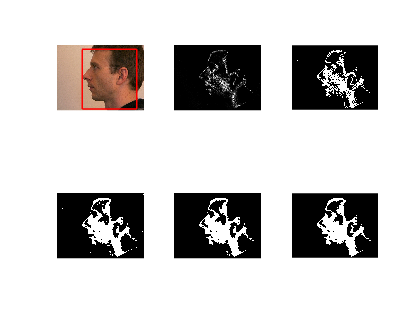

[res.Area];
wyczyszczony = bwareaopen(zamkniety,400); % dobierz parametry
subplot(2,3,5), imshow(wyczyszczony);

[x1, x2, twarz] = szukaj_twarz(wyczyszczony);
subplot(2,3,6), imshow(twarz);
%dodatkowa wizualizacja
subplot(2,3,1)
pos=[x1(2) x1(1) x2(2)-x1(2) x2(1)-x1(1)];
hold on;rectangle('Position',pos,'EdgeColor','red'); hold off

%trzecie zdjęcie testowe
testowy = imread('testowy_5_0000.jpeg');
figure, subplot(2,3,1), imshow(testowy);


szary2 = probabilityIM(testowy,model2);
subplot(2,3,2), imshow(szary2,[])
colormap(gray);


level =0.0012

level = 0.0012

binarny = im2bw(szary2, level);
subplot(2,3,3), imshow(binarny);

se = strel('disk', 6);% dobierz parametry element strukturalnego
zamkniety = imclose(binarny, se);
subplot(2,3,4), imshow(zamkniety);

label1 = bwlabel(zamkniety);
res = regionprops(label1)

res = 129×1 struct array with fields:
    Area
    Centroid
    BoundingBox


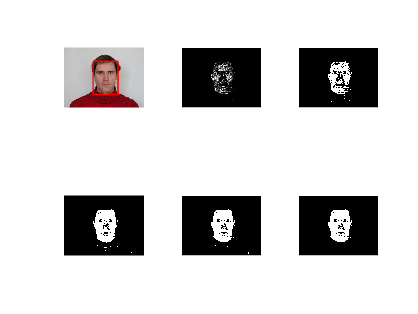

[res.Area];
wyczyszczony = bwareaopen(zamkniety,400); % dobierz parametry
subplot(2,3,5), imshow(wyczyszczony);

[x1, x2, twarz] = szukaj_twarz(wyczyszczony);
subplot(2,3,6), imshow(twarz);
%dodatkowa wizualizacja
subplot(2,3,1)
pos=[x1(2) x1(1) x2(2)-x1(2) x2(1)-x1(1)];
hold on;rectangle('Position',pos,'EdgeColor','red'); hold off

addpath("BazaObrazow")

testowy = imread('testowy_0_0000.jpeg');
faceDetector = vision.CascadeObjectDetector();

bbox = step(faceDetector, testowy)
Out = insertObjectAnnotation(testowy,'rectangle',bbox,'Twarz');
figure, imshow(Out), title('Wykryta twarz');

files = dir('BazaObrazow');

brak_detekcji=0;
detekcja=0;

for i=4:numel(files);
    nazw_pliku=files(i).name;
    testowy = imread(nazw_pliku);
    faceDetector = vision.CascadeObjectDetector();

    bbox = step(faceDetector, testowy)
    Out = insertObjectAnnotation(testowy,'rectangle',bbox,'Twarz');
    figure, imshow(Out), title('Wykryta twarz');


end
%za dużo jest obrazów tutaj żeby je wyświetlić

Program szukaj_twarzy.m raczej dobrze wyszukuje twarz tylko robi to z szyją. Daje radę nawet z zdjęcami z bocznego profilu, gdzie gotowy program matlaba nie daje rady.

Przy programie wykorzytsującym kaskady Haara nie udalo się wykryć twarzy na żadnym zdjęciu z profilu. W pozostałych przypadkach detekja się udała i dopasowanie było lepsze niż przy użyciu szukaj_twarz.m.

## Analiza i wnioski

Etapy wyznaczenia koloru skóry

- konwersja z RGB na YCbCr

- dobranie progów Cb i Cr

- obliczenie średniej i macierzy kowariancji

- wyznaczenie funkcji gęstości

Operacja zamknięcia sluży do usunięcia ,lub jeżeli to jest niemożliwe, wygładzenia dziur w obrazie.Składa się z dylatacji i erozji morfologicznej.

Użyci kaskad Haara świetnie sporawdza się przy zdjęciach frontalnych, daje dalej dobre wyniki przy zdjęciach z pół-profilu, a przy obrazach wykonanych z boku nie daje sobie rady.

## Pytania

Metody detekcji twarzy:

- PCA

- ICA

- LDA

- EP

- EBGM

- metody kernela

Metoda detekcji twarzy z wykorzystaniem kaskad Haara opiera się na zastosowaniu serii klasyfikatorów, które wykrywają cechy charakterystyczne. Proces ten wykorzystuje uczenie maszynowe, w którym kaskada jest trenowana na dużej liczbie obrazów zawierających twarze (przykłady pozytywne) oraz bez twarzy (przykłady negatywne). Kluczowym elementem tej metody jest wcześniejsze wyodrębnienie istotnych cech z obrazu.